clear;

## Question 1

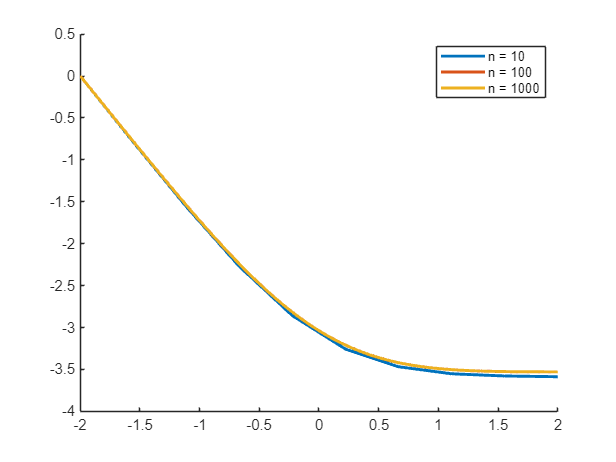

% ddu/dxx = exp(-x^2), u(-2) = 0, du/dx(2) = 0
% -2 <= x <= 2

% global parameters
xMin = -2; xMax = 2;
n = [10 100 1000];
cellDn = cell(1,3);
f = @(x) exp(-x.^2);

% setting up plot
fig1 = figure();
legend('location', 'northeast');
formatSpec = 'n = %d';

for index = 1:3
    % local parameters
    numPts = n(index);
    numInteriorPts = numPts - 2;
    h = (xMax-xMin) / (numInteriorPts+1); 
    xGrid = xMin : h : xMax;
    
    % constructing matrices
    c = [-2 1 zeros(1,numInteriorPts)];
    Dn = toeplitz(c);
    Fn = f(xGrid)';
    
    % imposing boundary conditions
    Dn(1,:) = [h^2 zeros(1,numInteriorPts+1)]; % u(-2) = 0;
    Fn(1) = 0;
    Dn(end,:) = [zeros(1,numInteriorPts-1) h -4*h 3*h]; % du/dx(2) = 0;
    Fn(end) = 0;
    
    Dn = Dn/h^2;
    cellDn{index} = Dn;
    
    % solution
    Un = Dn \ Fn;
    
    % plot
    str = sprintf(formatSpec, n(index));
    hold on;
    plot(xGrid', Un, 'LineStyle', '-', 'LineWidth', 2, ...
        'DisplayName', str);
end

## Question 2

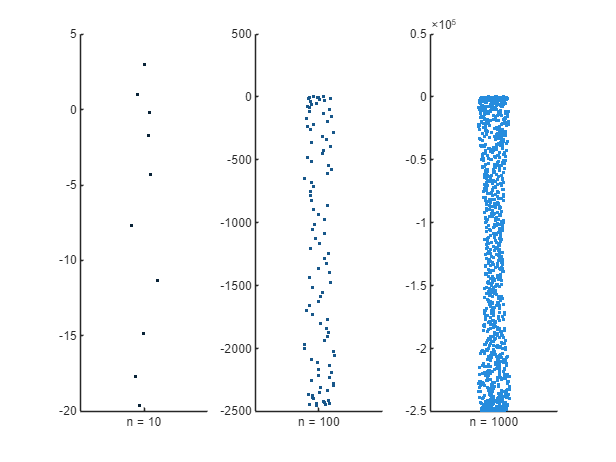

% dY/dt = -5 Dn Y(t)
% Y(0) = phi = Un

c = abyss(3);
fig2 = tiledlayout(1,3);

for index = 1:3
    Dn = cellDn{index};
    ew = eig(Dn);
    
    nexttile;
    hold on;
    xlim([-1 1]);
    xticks(0);
    str = sprintf(formatSpec, n(index));
    xticklabels(str);

    swarmchart(zeros(length(ew),1), ew, [], c(index,:), '.', 'XJitter', 'density', 'XJitterWidth', 0.5);
end